# **Mobile Rover Calibration**

This is the calibration script that will help the localization algorithm determine the location of the rover and the target. Additionally, it will tune the variables to represent the arena's environmental conditions. **This script needs to be run following any changes to the set-up or lighting conditions.**

## Step 1: Prepare the MATLAB Workspace

Before we start anything, let's clear the workspace, clear the command window and close any figures.

clear;
close all;
clc;

## Step 2: **Enter the arena's dimensions **

Before we perform any of the calibration algorithms, we first need to specify the dimensions of the arena. These measurements will be used to translate the image so that it is viewed from above (the orthogonal view). 

**Please ensure that you enter the actual arena measurements that you obtained while building the arena. **Otherwise, the localization results may be inaccurate. 

% Enter the arena dimensions in centimeters
arenaHeight= 43;
arenaWidth = 41;

## Step 3: I**nitialize the webcam and compute the transformation that gives the orthogonal view**

Next, a webcam object needs to be created to initialize the image feed from the camera. **Please ensure that the four corners of the arena are visible in the webcam preview; the entire rover should also be visible when it is placed on the boundaries of the arena.** **Once the entire rover and arena are visible in the video preview, please enter "yes" in the MATLAB Command Window.**

% Initialize the webcam
cam = webcam('USB2.0 PC CAMERA');
preview(cam);
response = 'no';
while ~strcmpi(response,'yes')
    response = input('Once you can see the entire arena and the rover in the preview, please enter "yes": \n','s');
    clc;
end
closePreview(cam);

To account for the fact that your camera is looking at the arena with a perspective view, we will need to calibrate the image and compute the transformation that can give us the orthogonal view of the rover. **We will do this by selecting the four corners of the arena in the image. **

**During this section, the rover should be visible in the arena.** Otherwise, you will not be able to properly calibrate the RGB color values later in this exercise. 

% Take a snapshot
im = snapshot(cam);

% Compute the transformation for the orthogonal view
[orthoImg, tform, outputView, outputSize, newCorners] = calibrateOrthoView(...
    im, arenaHeight, arenaWidth);

## **Step 4a: Compute the location offset for the rover**

When translating the image to the orthogonal view, there will be some distortion due to the angle between the camera and the arena. To compensate for this, **we will need to capture images of the rover on the four edges of the arena.**

**Let's begin with an image of the rover at the top of the arena**. It should look something like this:

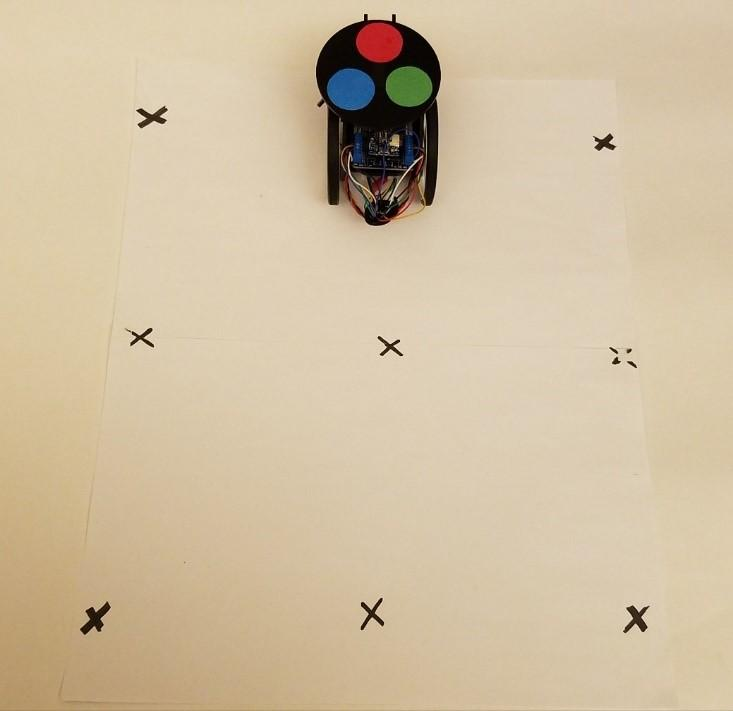

% Take an image with the rover at the top of the arena
reTakeImage = true;
while reTakeImage
    [imUp, reTakeImage] = takeSnapForOffset(cam,'rover','TOP');
end

% To see an example of a bad image, uncomment the line below.
% This image is bad because it is very blurry and you cannot see the entire rover.
% imshow(badImage.jpg);

**Now, let's take an image of the rover at the bottom of the arena**. It should look something like this:

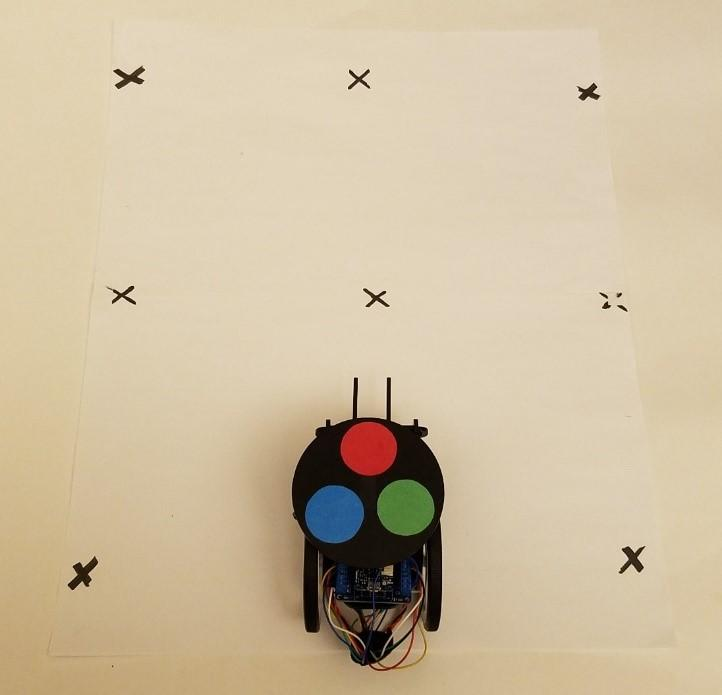

% Take an image with the rover at the bottom of the arena
reTakeImage = true;
while reTakeImage
    [imDown, reTakeImage] = takeSnapForOffset(cam,'rover','BOTTOM');
end

**Now, let's take an image of the rover on the left edge of the arena.** It should look something like this:

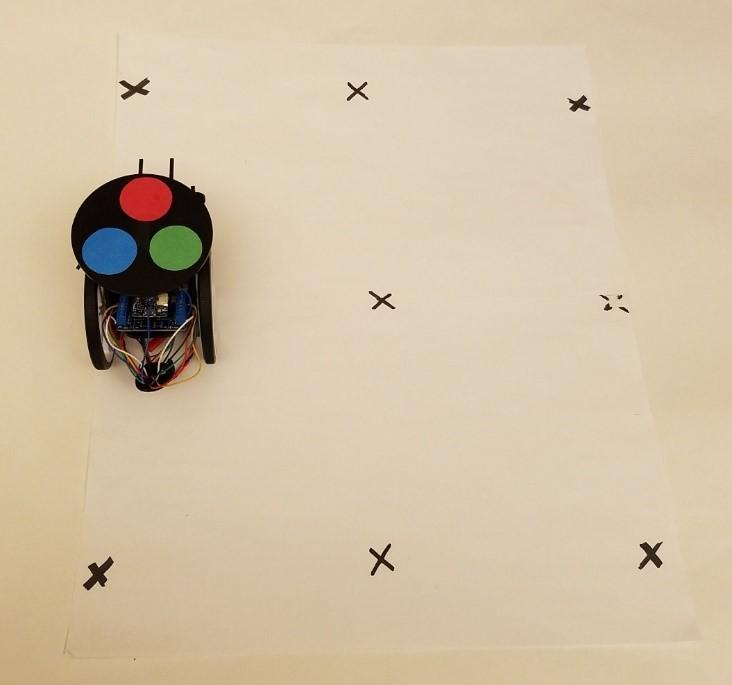

% Take an image with the rover on the left edge of the arena
reTakeImage = true;
while reTakeImage
    [imLeft, reTakeImage] = takeSnapForOffset(cam,'rover','LEFT');
end

**Now, let's take an image of the rover on the right edge of the arena.** It should look something like this:

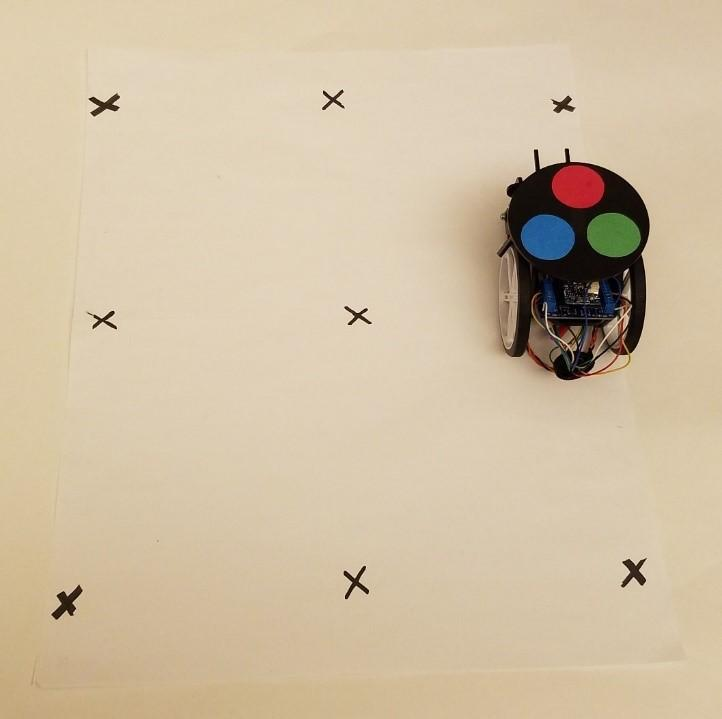

% Take an image with the rover on the right edge of the arena
reTakeImage = true;
while reTakeImage
    [imRight, reTakeImage] = takeSnapForOffset(cam,'rover','RIGHT');
end

## **Compute the offsets of the rover **

**By selecting the points specified in the pop-up figures (the center of the rover and the center of the disc), **the 'calibrateLocationOffset' algorithm will help compensate for the distortion in the orthogonal image. 

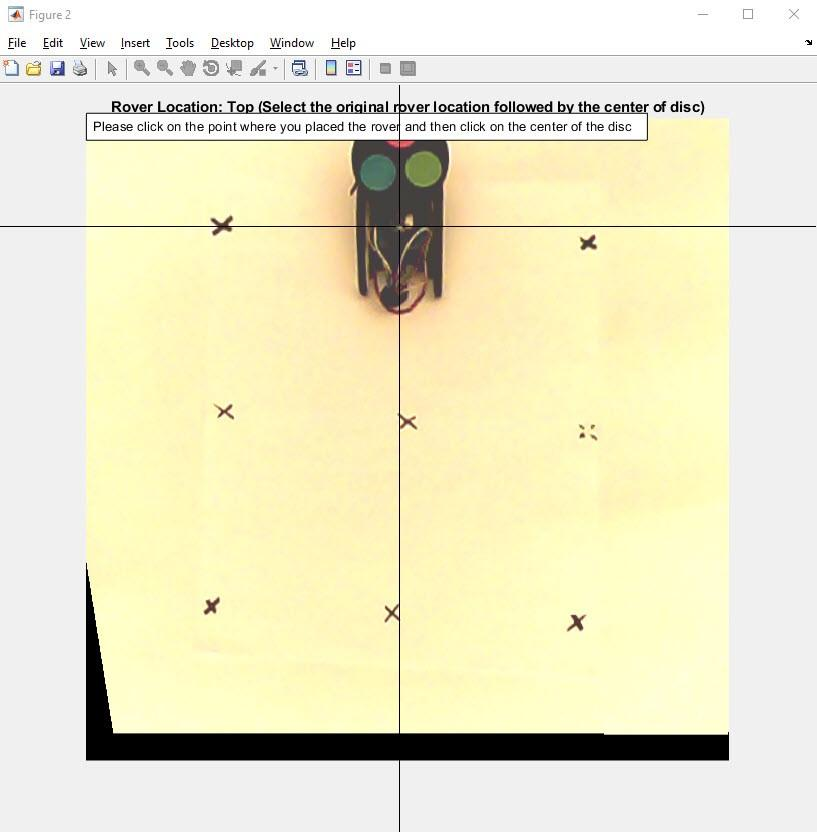

% Compute the offsets for the rover
[horzOffsetRange, verticalOffsetRange] = calibrateLocationOffset('rover',...
    imUp, imDown, imLeft, imRight,...
    tform,outputView, outputSize(1:2));

## Step 4b: **Compute the location offset f**or the target

Just as we calibrated the location offset for the rover, **we will now need to calculate the location offset for the target. **This is because the offset values vary depending on the height of the object and the distance of the object from the camera.

% Take an image with the target at the top of the arena
reTakeImage = true;
while reTakeImage
    [imUpTarget, reTakeImage] = takeSnapForOffset(cam,'target','TOP');
end

% Take an image with the rtarget at the bottom of the arena
reTakeImage = true;
while reTakeImage
    [imDownTarget, reTakeImage] = takeSnapForOffset(cam,'target','BOTTOM');
end

% Take an image with the target on the left edge of the arena
reTakeImage = true;
while reTakeImage
    [imLeftTarget, reTakeImage] = takeSnapForOffset(cam,'target','LEFT');
end

% Take an image with the target on the right edge of the arena
reTakeImage = true;
while reTakeImage
    [imRightTarget, reTakeImage] = takeSnapForOffset(cam,'target','RIGHT');
end

## Compute the offsets of the target

When we calculate the location offset for the target, **we will need to select the location where the target was placed followed by the center of the target.** Otherwise, the localization results may be inaccurate and can cause issues when navigating the rover throughout the arena. The following image is an example of clicking on the center of the target:

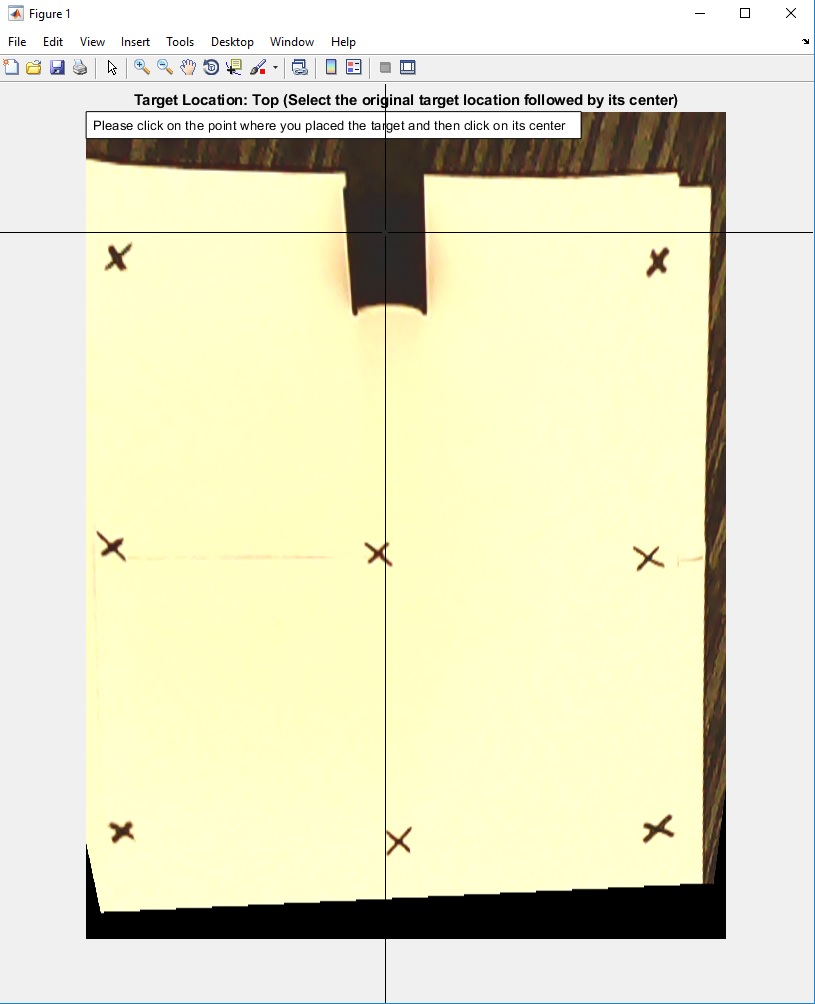

% Calibrate offsets for the target
[horzOffsetRangeTarget, verticalOffsetRangeTarget] = calibrateLocationOffset('target',...
    imUpTarget, imDownTarget, imLeftTarget, imRightTarget,...
    tform,outputView, outputSize(1:2));

## **Step 5: Calibrate the color threshold of the disc**

The lighting may affect the how the webcam detects colors so we will need to calibrate the reference values using the colored circles located on the rover's disc. **You will need to click on the three colored circles on top of the rover. You should click the circles in this order: **Red first, then Green and then finally Blue 

Once you click these circles,** you should press the 'ENTER' key to confirm your selections. **

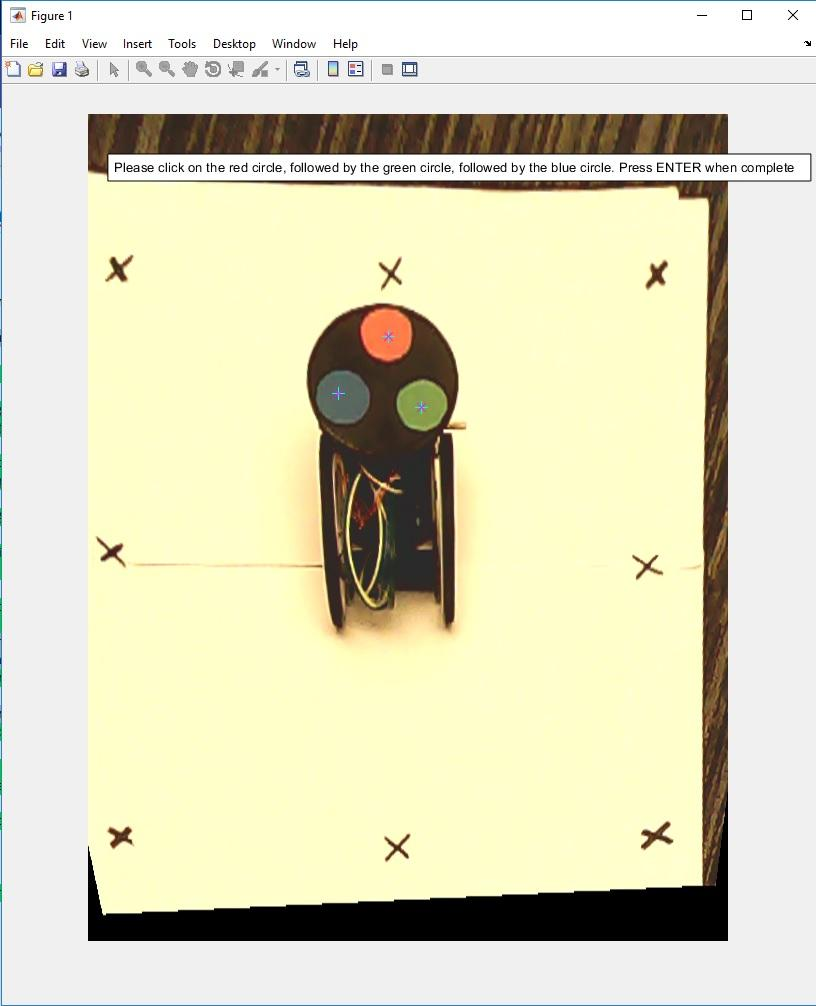

% Calibrate RGB Colors
calibrateColorThresh(orthoImg);

*Copyright 2018 - 2020 The MathWorks, Inc.*